disp('Scara PRR')

Scara PRR


disp('Mendoza')

Mendoza


syms a1 a2 a3 a4 a5 d1 t2 t3

%% Link lengths
a1 = 3;
a2 = 2;
a3 = 2;
a4 = 2;
a5 = 2;

%% Joint variables
d1 = 3;

%% D-H Parameters[theta,d,r,alpha,offset]
% prismatis joint: theta = theta, d = 0, offset = 1, after offset value put value d
% revolute joint: theta = 0, offset = 0, after offset put the value of theta

H0_1 = Link([0,0,0,0,1,a1]);
H0_1.qlim = [0 0];

H1_2 = Link([0,0,a3,0,1,a2]);
H1_2.qlim = [0 d1];

H2_3 = Link([0,0,a4,0,0,0]);
H2_3.qlim = [-pi/2 pi/2];

H3_4 = Link([0,0,a5,0,0,0]);
H3_4.qlim = [-pi/2 pi/2];

Scara = SerialLink([H0_1 H1_2 H2_3 H3_4], 'name', 'Scara')

 
Scara = 
 
Scara:: 4 axis, PPRR, stdDH, slowRNE                             
+---+-----------+-----------+-----------+-----------+-----------+
| j |     theta |         d |         a |     alpha |    offset |
+---+-----------+-----------+-----------+-----------+-----------+
|  1|          0|         q1|          0|          0|          3|
|  2|          0|         q2|          2|          0|          2|
|  3|         q3|          0|          2|          0|          0|
|  4|         q4|          0|          2|          0|          0|
+---+-----------+-----------+-----------+-----------+-----------+
 


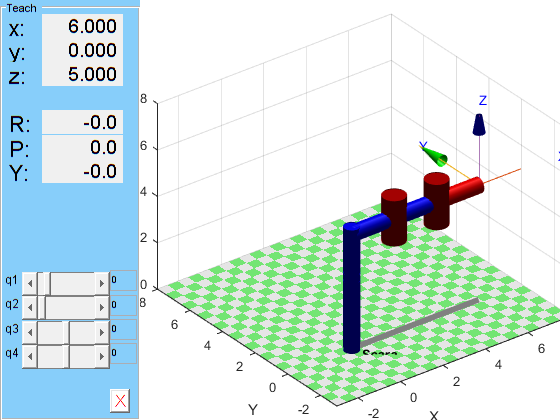

Scara.plot([0 0 0 0], 'workspace', [-3 8 -3 8 0 8])
Scara.teach